### **Bildvergleich** (Lea, Clara)

Für den Bildvergleich betrachten wir nur die Helligkeitsverteilung von Bildern. Diese liegen zwischen Schwarz und Weiß und nehmen daher Werte zwischen 0 und 1 an. Bei der Umsetzung als Programm sind die Helligkeitswerte Integer und reichen zbsp. von 0 bis 255. (= digital quantisiertes Bild).

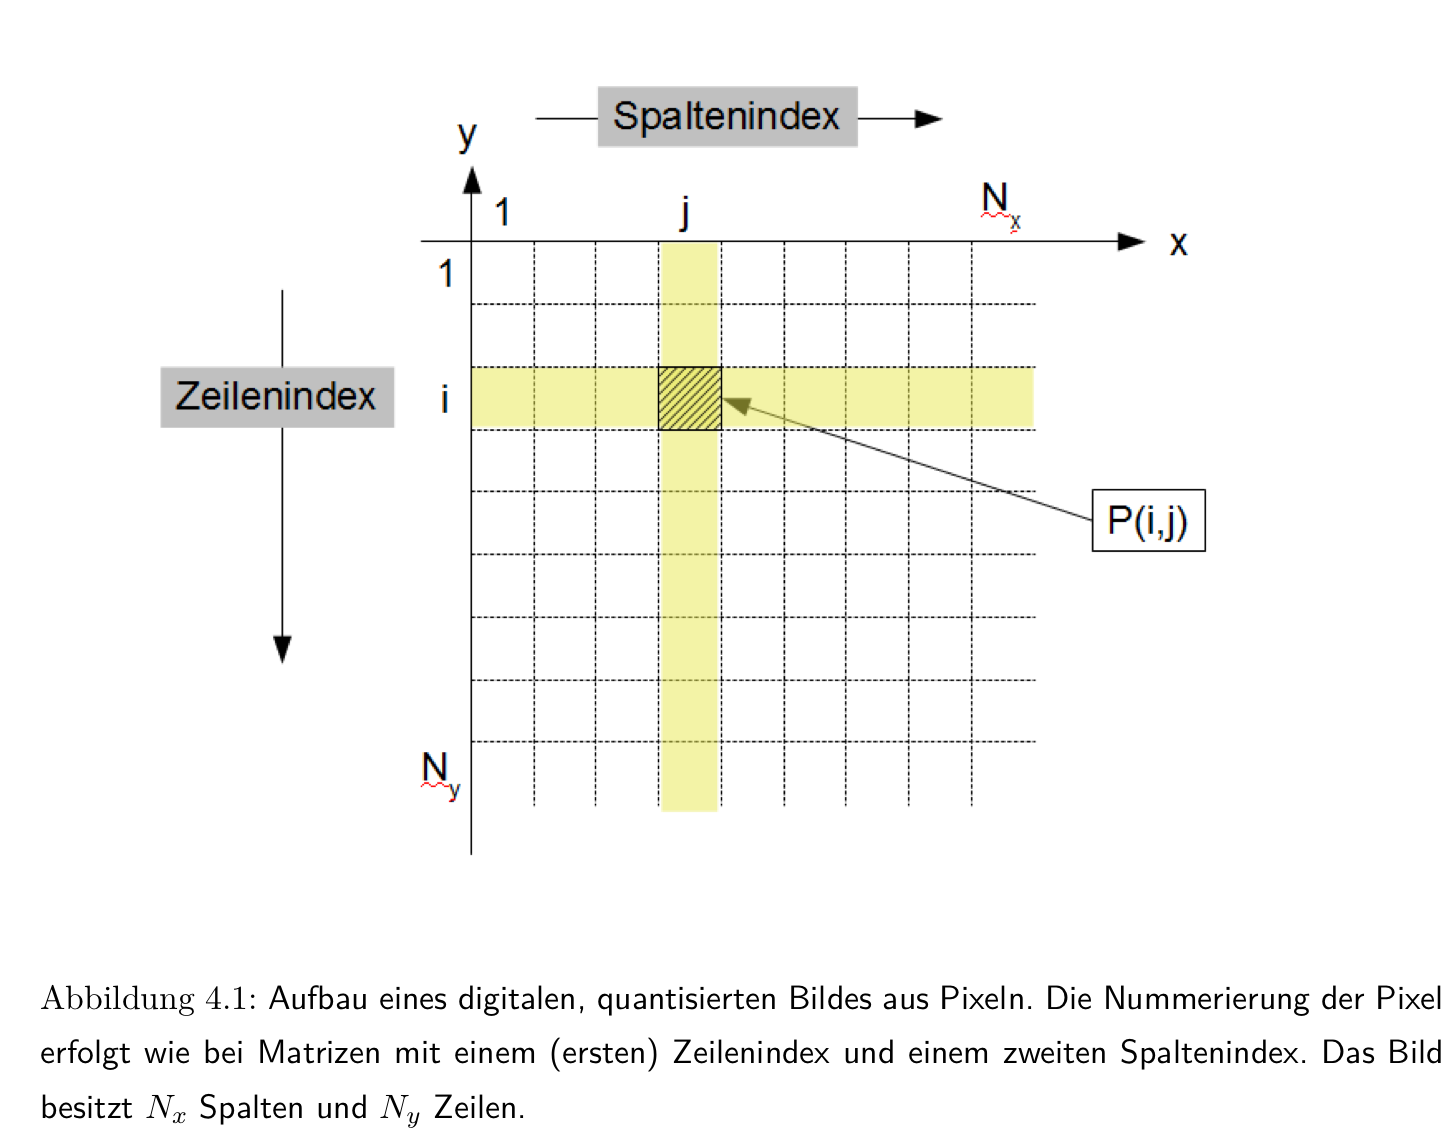 

(Quelle: Fuchs, C.: Computer Tomopgrafie Skript. 2022)

Für die Simulation eines tomografischen Verfahrens soll betrachtet werden, wie gut das Ergebnisbild R das ursprüngliche Bild A reproduziert. Dafür haben wir 5 Kennzahlen betrachtet.

% Einfaches Beispiel eines Augangsbild A und Ereignisbildes R
R = [[1,2,3];[1,2,3]];
A = [[1,2,3];[1,2,4]];

**Kennzahl 1**

Delta 1 wird 0, wenn die Bilder A und R gleich sind.


$$\Delta_1 \left(R,A\right)=\frac{1}{N_{x\;} N_y }\;\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|r_{\textrm{ij}} -a_{\textrm{ij}} \right|$$


del1 = (1/ (size(A,1)*size(A,2))) * sum(sum(abs(R-A)));
disp(del1)

    0.1667



**Kennzahl 2**

Delta 1 wird 0, wenn die Bilder A und R gleich sind.


$$\Delta_2 \left(R,A\right)=\sqrt{\frac{1}{N_{x\;} N_y }\;\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left|r_{\textrm{ij}} -a_{\textrm{ij}} \right|}^2 }$$


del2 = sqrt((1/ (size(A,1)*size(A,2))) * sum(sum((R-A).^2)));
disp(del2)

    0.4082



Da es schwer ist auf den Kennzahlen 1 und 2 Rückschlüsse über die Güte der Bildrekonstruktion zu ziehen, werden weitere Kennzahlen benutzt.

**Kennzahl 3**


$$\Delta_3 \left(R,A\right)=\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} -r_{\textrm{ij}} \right)}^2 }{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} +r_{\textrm{ij}} \right)}^2 }$$


Da $a_{\textrm{ij}}$ und $r_{\textrm{ij}}$ positiv sind, gilt: $0\le \Delta_3 \left(R,A\right)\le 1$

Wenn $\Delta_3$ = 0 ist, sind die Bilder wieder gleich. Bei $\Delta_3 \left(R,A\right)$ = 1 gilt die Bedingung: 

$\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } a_{\textrm{ij}} r_{\textrm{ij}} =0$, $\forall i\;\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_x \right\rbrace ,j\;\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_y \right\rbrace \;a_{\textrm{ij}} r_{\textrm{ij}} =0$

Das heißt Pixelwerte am gleichen Pixel können nicht von 0 verschieden sein. Wichtig ist außerdem, dass der Wertebereich von $\Delta_3$ nach oben beschränkt ist (wegen der Quantisierung der Pixelwerte).

del3 = sum(sum((A-R).^2)) / sum(sum((A+R).^2));
disp(del3)

    0.0080



Zwei weitere Kennzahlen aus der Literatur wurden umgesetzt:

**Kennzahl 4**

$\Delta_4$ ist Null, wenn beide Bilder identisch sind. $\Delta_4$ wird groß, wenn viele kleine Unterschiede auftreten. Außerdem gilt:


$$\Delta_4 \left(R,A\right)=1\leftrightarrow r_{\textrm{ij}} =\bar{a} \;\forall i\;$$

$$\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_x \right\rbrace ,j\;\epsilon \;\left\lbrace 1,\ldotp \ldotp \ldotp ,N_y \right\rbrace$$


Es wird ein homogenes Bild berechnet, dessen Mittelwert dem Mittelwert des ursprünglichen Bildes A entspricht. Schon kleine Bildunterschiede zwischen A und R sind bereits wesentlich, wenn sich A nur gering von einem konstanten Bild mit gleichem Mittelwert unterscheidet. 


$$\Delta_4 \left(R,A\right)=\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} -r_{\textrm{ij}} \right)}^2 }{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } {\left(a_{\textrm{ij}} -\bar{a} \right)}^2 }$$


del4 = sum(sum((A-R).^2)) / sum(sum((A-(mean(A,"all"))).^2));
disp(del4)

    0.1463



**Kennzahl 5**

$\Delta_5$ ist Null, wenn beide Bilder identisch sind.


$$\Delta_5 \left(R,A\right)=\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} -r_{\textrm{ij}} \right|}{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} \right|}$$


del5 = sum(sum(abs(A-R))) / sum(sum(abs(A)));
disp(del5)

    0.0769



**Uniformity Index (Gleichheitsindex)**

Zur Bewertung der Homogenität eines Bildes, kann man $\rho_{\textrm{UI}} \left(A\right)$ berechnen. Das Bild A wird dabei mit einem homogenen Bild B verglichen, dessen Pixelwerte dem Mittelwer von A entsprechen.

Der Gleicheitsindex nimmt den Wert 1 an, wenn das Bild A homogen ist.


$$\rho_{\textrm{UI}} \left(A\right)=1-\frac{1}{2}\;\frac{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} -\bar{a} \right|}{\sum_{j=1}^{N_x } \sum_{i=1}^{N_y } \left|a_{\textrm{ij}} \right|}$$


uniformity = 1 - 1/2 *(sum(sum(abs(A-mean(A,'all'))))/sum(sum(abs(A))));
disp(uniformity)

    0.7949



Insgesamt geben die Kennzahlen in der Praxis Werte zur Orientierung an. Besonders beim Betrachten vieler Beispiele, können Kennzahlen schnell eine Einschätzung geben.

### Paralleltomo Miriam, Daniel

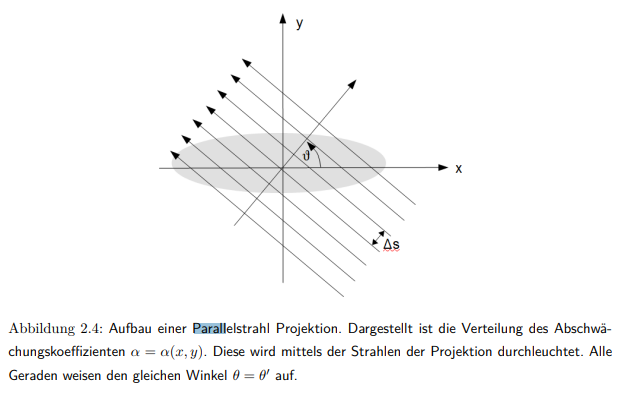

#### Parameter

- N            Zellen/Pixel pro Zeile/Spalte

- theta        Vektor mit verwendeten Winkeln

- p             Anzahl an  parallelen Strahlen pro Winkel

- d             Abstand des ersten und des letzten Strahls zueinander

- isDisp     Boolean, ob Zwischenergebnisse angezeigt werden sollen

N = 250;
theta = 0:179;
p = round(sqrt(2)*N);
d = sqrt(2)*N;
isDisp = 0;

[A, b, x, theta, d, p] = paralleltomo(N,0,theta,p,d,isDisp); %#ok<*ASGLU> 

**Relevante Rückgabewerte**

- x:  Vektor mit exakter Lösung

- A:  Koeffizientenmatrix

- b:  Vektor zur Matrix

**Lösen des Gleichungssystemes**

K = 20; % Anzahl der Iterationen
[X,info] = kaczmarz(A,b,K);  

**Anzeigen der Rekonstruktion und des Originals**

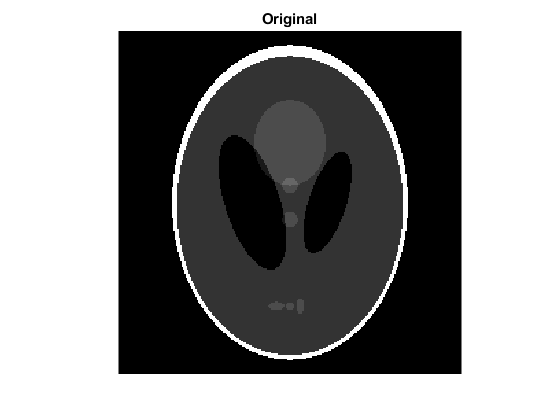

figure;
imagesc(reshape(x,N,N)), colormap gray,
axis image off
c = caxis;
title('Original');

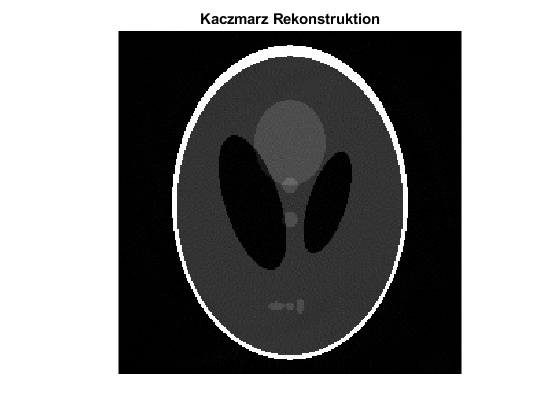

figure
imagesc(reshape(X,N,N)), colormap gray,
axis image off
caxis(c)
title('Kaczmarz Rekonstruktion')

**Verschiedene Bilder:**

### Fächerstrahltomographie

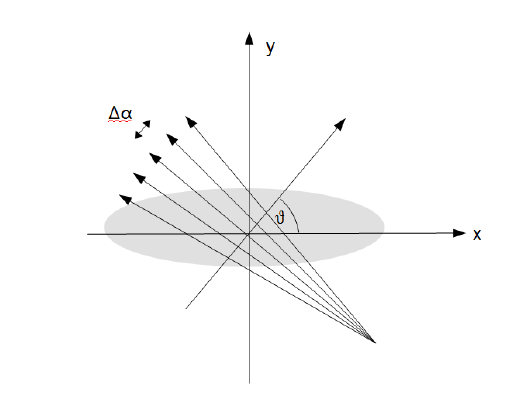

#### Parameter

- N            Zellen/Pixel pro Zeile/Spalte

- theta       Vektor mit verwendeten Winkeln

- p             Anzahl an Strahlen pro Winkel

- R            Abstand von Sender zum Mittelpunkt des Objekts

- d             Spannweite der Strahlen

- isDisp     Boolean, ob Zwischenergebnisse angezeigt werden sollen

N = 100;
theta = 0:1:359;
p = round(sqrt(2)*N);
R = 2;
d = 2*atand(1/(2*R-1));
isDisp = 0;

#### Absoptionskoeffizient

Hier kann ein beliebiger Absorptionskoeffizient erstellt werden

**Beispielsweise:**

- Beispelbilder

- Einzelne Matrizen von Hand

- Phantombilder

**Phantomgallerie:**

Matlab Funktion, die verschiedene Phantombilder erzeugen kann. Diese sind besonders zum Testen von Rekonstruktionen geeignet. 

- smooth

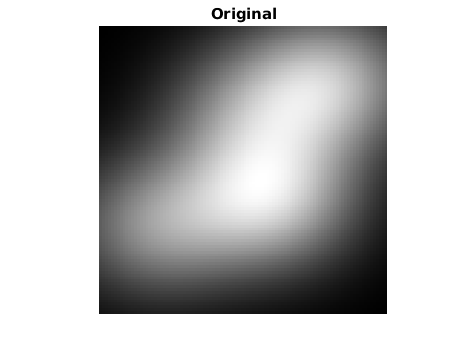

- binary

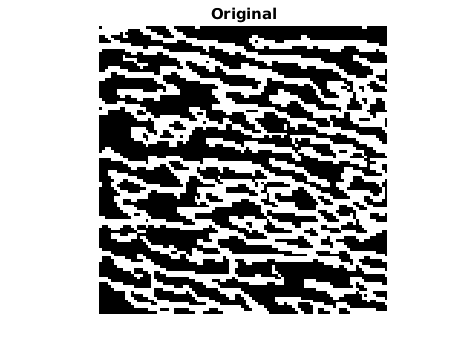

- treephases

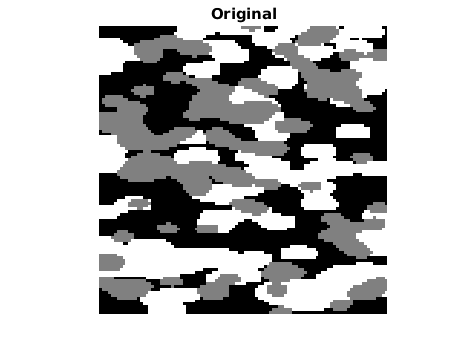

- treephasessmooth

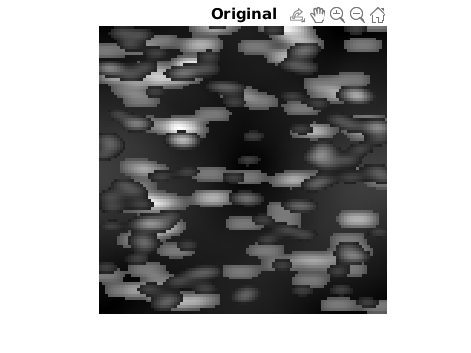

- fourphases

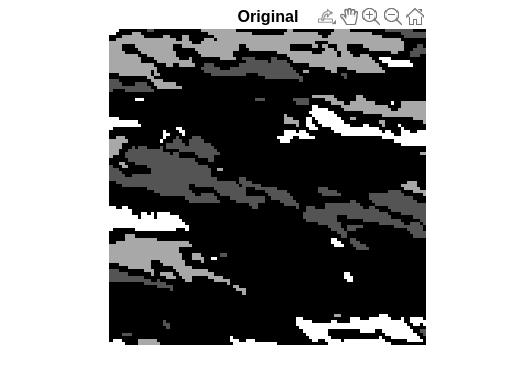

- grains

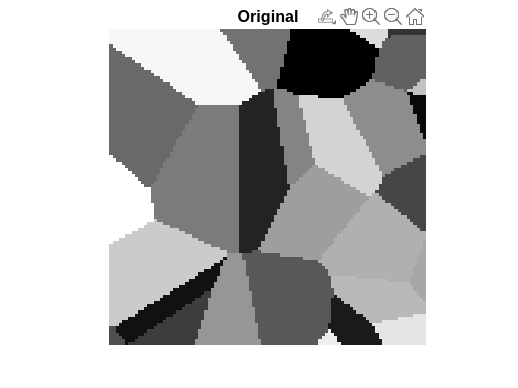

- ppower

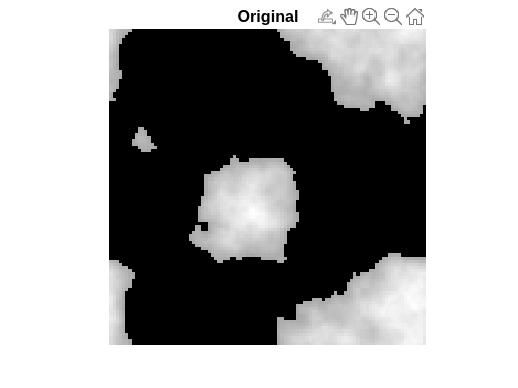

**Änderungen an *****fanbeamtomo.m:***

absCoeff = phantomgallery('smooth',N);

[A, b, x, theta, d, p] = fanbeamtomo(N,theta,p,R,d,isDisp, absCoeff);

**Relevante Rückgabewerte**

- x:  Vektor mit exakter Lösung

- A:  Koeffizientenmatrix

- b:  Vektor zur Matrix

#### Lösen des Gleichungssystemes

K = 5; % Anzahl der Iterationen

[X,info] = kaczmarz(A,b,K);

#### Anzeigen der Rekonstruktion und des Originals

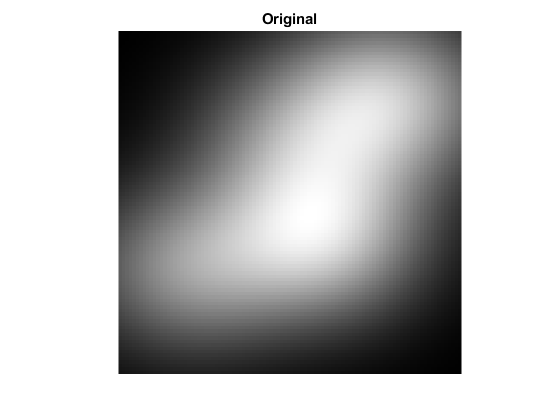

figure;
imagesc(reshape(x,N,N)), colormap gray,
axis image off
c = caxis;
title('Original');

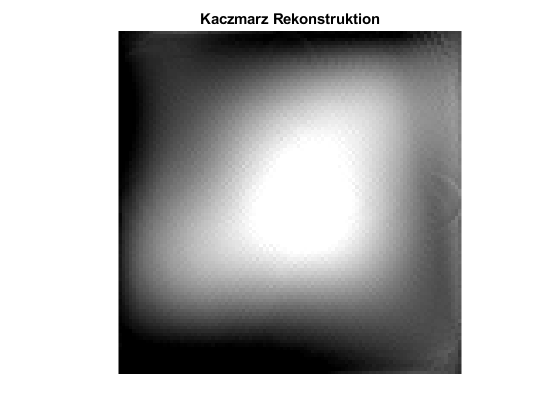

figure
imagesc(reshape(X,N,N)), colormap gray,
axis image off
caxis(c)
title('Kaczmarz Rekonstruktion')

#### Numerisches Vergleichen der Bilder

Berechnen der Vergleichswerte

[del1,del2,del3,del4,del5, uniformity] = bildvergleich(x,X);

del1:

disp(del1);

    0.1175



del2:

disp(del2);

    0.1426



del3:

disp(del3);

    0.0162



del4:

disp(del4);

    0.1947



del5:

disp(del5);

    0.2417



uniformity:

disp(uniformity);

    0.7231



#### Visuelles Vergleichen der Bilder 

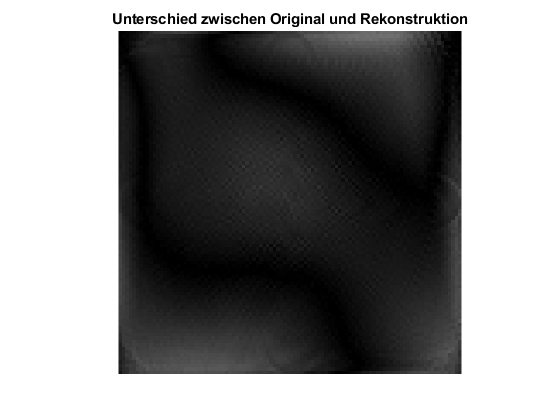

l = abs(X-x);

figure
imagesc(reshape(l,N,N)), colormap gray,
axis image off
caxis(c)
title('Unterschied zwischen Original und Rekonstruktion')